# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{
    
    run_bks.mlx
    ----------

    This code runs all codes to solve the partial equilibrium decentralized model with occupational choice.
	
%}

## Model: Decentralized Model with Occupational Choice.

The model is solved as decentralized problem where infinitely-lived households must choose between being workers or entrepreneurs. Popuation is normalized to 1, $N_t=1$, and some of fraction of these are workers $L_t<N_t$. The household's problem when they are workers is


$$\underset{\{c_t\}_{t=0}^{\infty},\{a_{t+1}\}_{t=0}^{\infty}}{\text{max }} \mathbb{E}_0 \sum_{t=0}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } c_t + a_{t+1} = (1+r)a_t + w_t\ ,$$



$$c_t > 0 \ , $$



$$a_t \ \text{is given} \ ,$$


where $w_t$ is the wage rate that households take as given and the constraints hold for $t = 1, 2, ...,$. The household's problem when they are entrepreneurs is


$$\underset{\{c_t\}_{t=0}^{\infty},\{a_{t+1}\}_{t=0}^{\infty}}{\text{max }} \mathbb{E}_0 \sum_{t=0}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\text{s.t. } c_t + a_{t+1} = (1+r)a_t + \pi_t \ ,$$



$$c_t > 0 \ , $$



$$a_t \ \text{is given} \ ,$$


where $\pi_t$ is the profit of the firm and the constraints hold for $t = 1, 2, ...,$. Firms are in perfectly competitive markets and so take prices as given. The firm's problem is static and given by


$$\underset{K_t,L_t}{\text{max }} e^{\epsilon_t}K_t^{\alpha}L_t^{1-\alpha} - w_tL_t - R_tK_t -(1+r_t)\kappa \text{ ,}$$


 
$$\text{s.t.} \ K_t \leq \bar{K}(a,\epsilon,\phi) \ ,$$


where $\epsilon_{t}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$ and the rental limit, $\bar{K}(a_t,\epsilon_t,\phi)$, satisfies


$$\underset{L_t}{\text{max }} e^{\epsilon_t}K_t^{\alpha}L_t^{1-\alpha} - w_tL_t - R_tK_t -(1+r_t)\kappa + (1+r)a_t \geq 
(1-\phi)\left[\underset{L_t}{\text{max }} e^{\epsilon_t}K_t^{\alpha}L_t^{1-\alpha} - wL_t + (1-\delta)K_t\right] \ .$$


The intuition in the constraint above is that firms will not default on their rental contracts for capital if the profit from doing so exceed the profit if their assets, excluding undepreciated capital, are garnished. The model is solved in partial equilibrium so $r$ and $w$ are set exogenously and do not adjust to equate supply and demand. Similarly, $L_t$ is set exogenously, which firms taken as given, and $K_t$ is obtained from the first order conditions of the firm, given fixed $w_t, r_t, \delta,$ and $K_t$.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:/Users/',id,'/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/notes/code/bks/'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

fprintf('The directory is %s \n\n',main)

The directory is C:/Users/xmgb/Dropbox/02_FUV/teaching/spring_2025/dynamic_macro/notes/code/bks/ 



## Set the parameters and generate the state space.

Calls: model.m.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model in partial equilibrium.

Solve the model taking prices as given.

Calls: solve.m.

[par,sol] = solve.firm_problem(par); % Firms.


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

sol = solve.hh_problem(par,sol); % Households.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.

Converged in 272 iterations.

------------End of Value Function Iteration.------------


## Plot policy functions.

Calls: my_graph.m

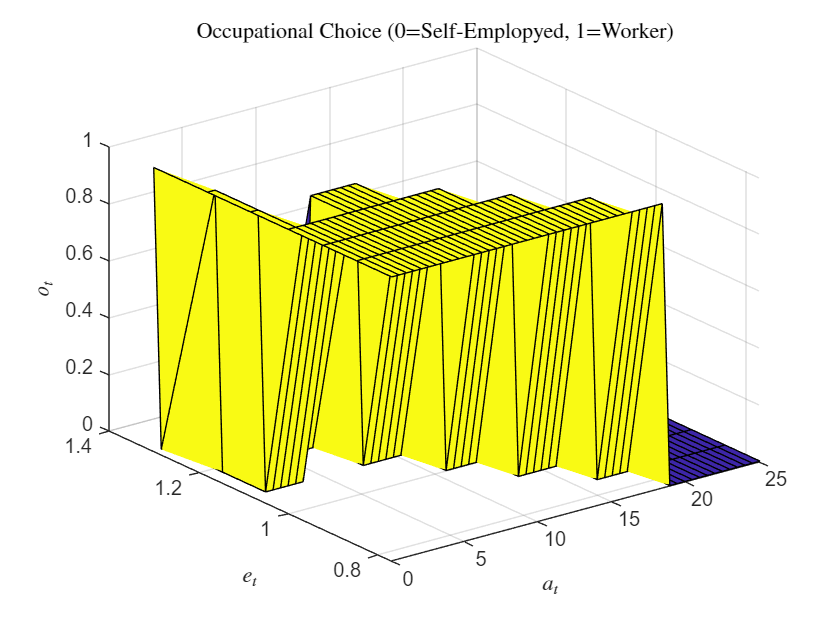

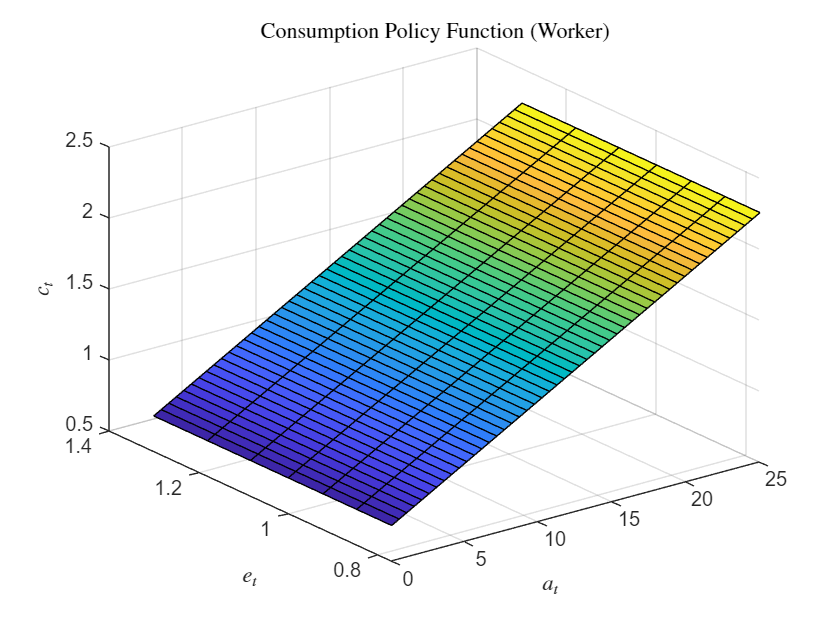

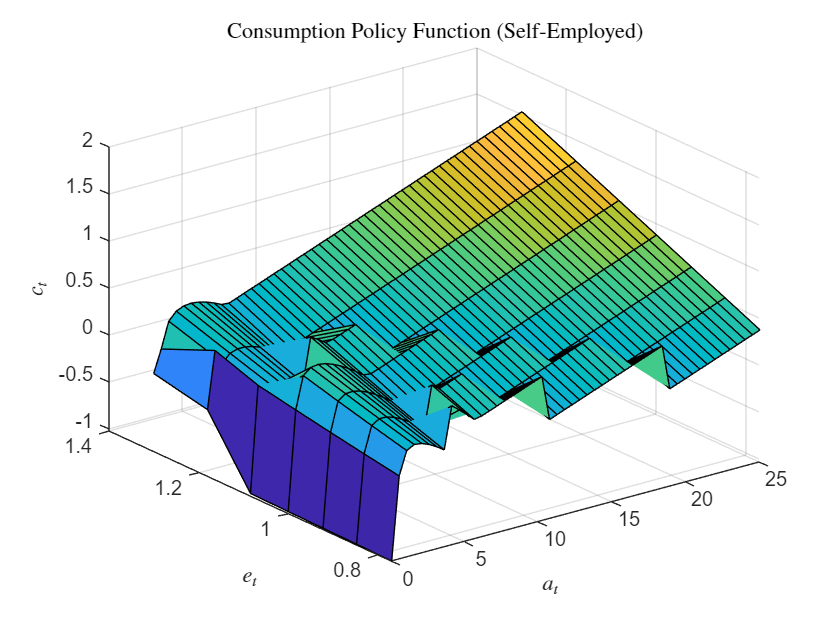

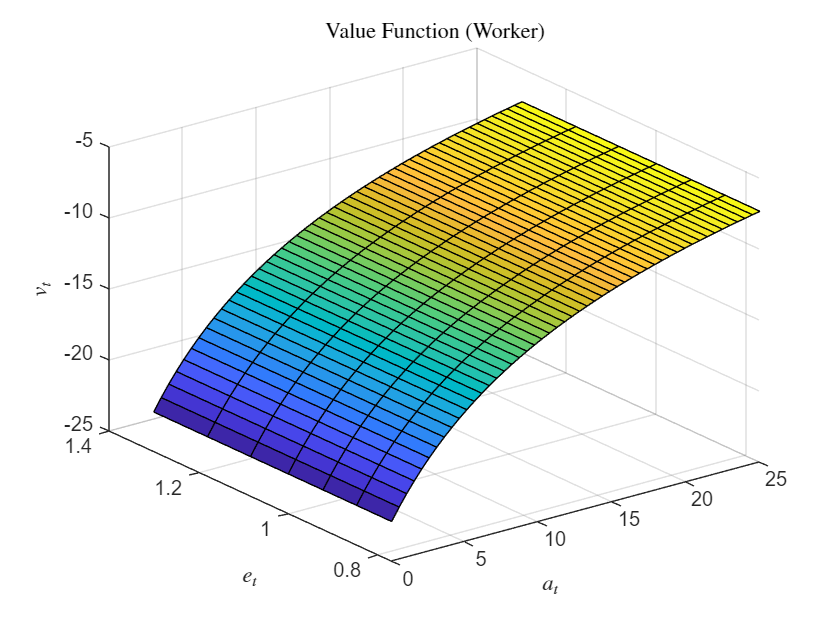

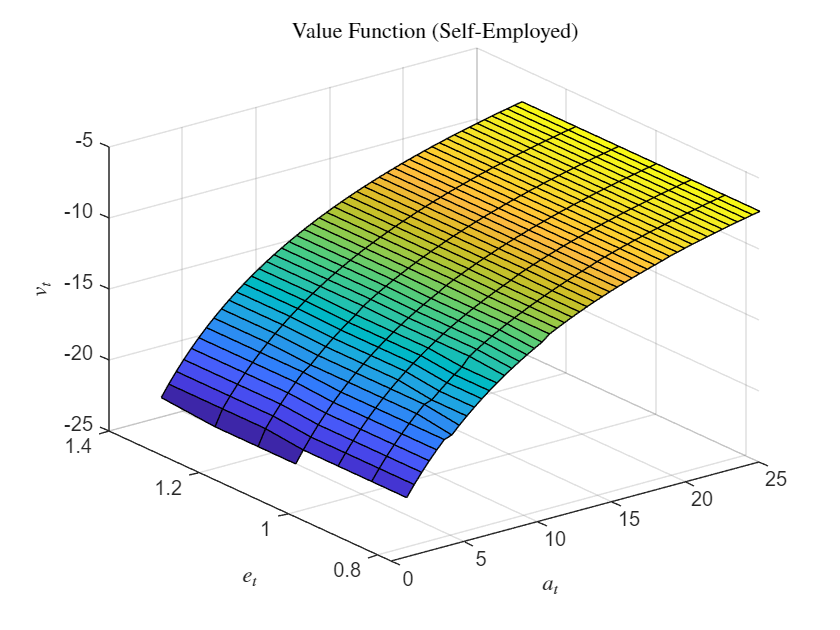

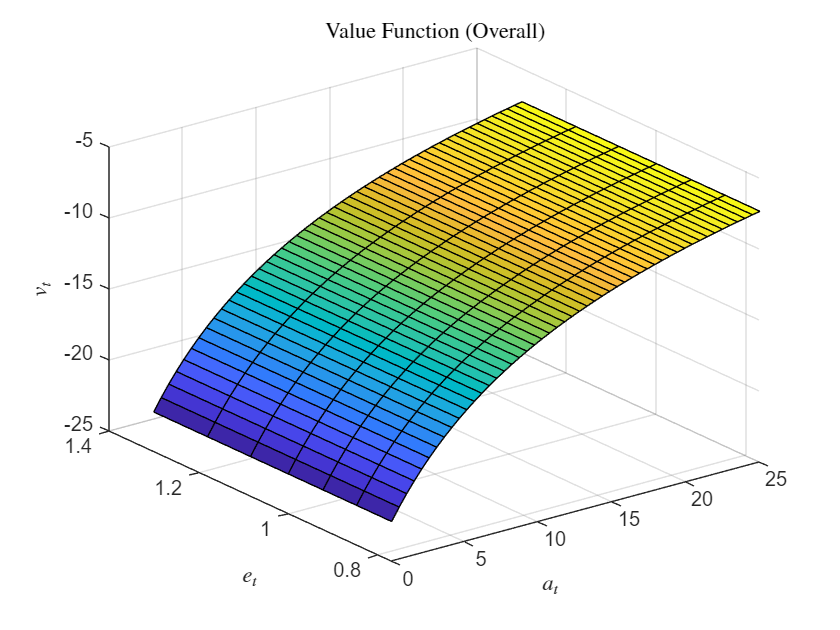

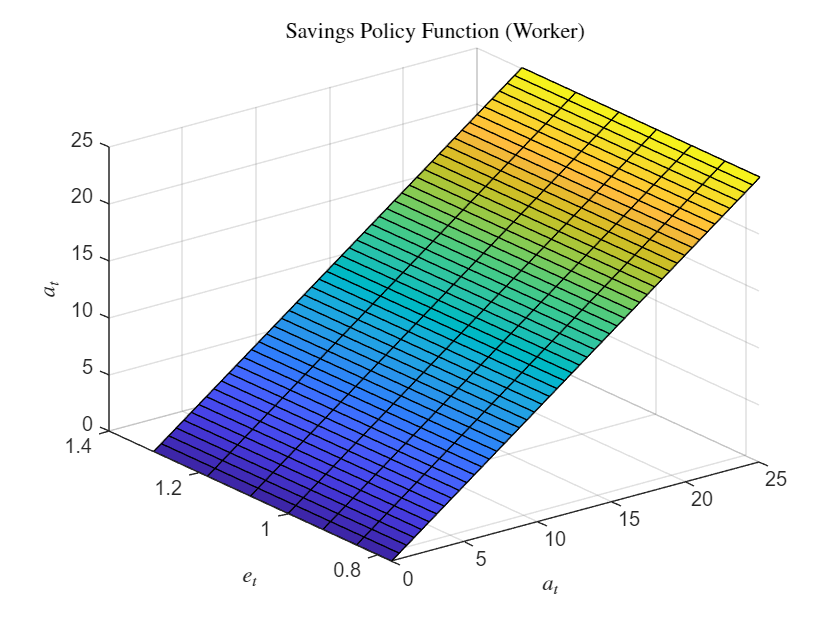

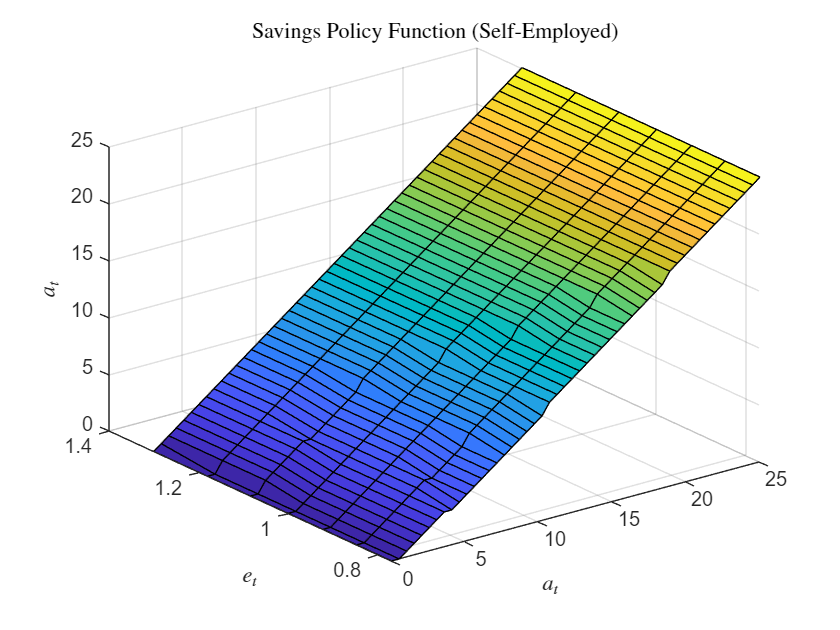

my_graph.plot_policy(par,sol) % Plot the policy functions.